clear; clc; close all;

%% =========================================================
% Fast numerical workspace estimation (q1,q2,q3,q4 sweep)
% Modified so that q1 = 0 faces the chessboard (+Y direction)
%% =========================================================

%% =========================
% Robot dimensions
%% =========================
b  = 2.5;
L1 = 5;
L2 = 18;
L3 = 12;
L4 = 6;

%% =========================
% Chessboard parameters
% Base is at the centre of the bottom edge
% So board spans:
%   x in [-15, 15]
%   y in [0, 30]
%% =========================
board_size   = 30;
board_x_min  = -board_size/2;
board_y_min  = 0;
board_z      = 0;

piece_height = 4;
lift_height  = 2 * piece_height;

%% =========================
% Joint ranges
% IMPORTANT: use coarser step first for speed
%% =========================
q1_range = linspace(-pi/2, pi/2, 41);      % 41 points
q2_range = deg2rad(-140:10:0);
q3_range = deg2rad(-140:10:0);
q4_range = deg2rad(-140:10:0);

% q5 removed: position unaffected in this DH model

%% =========================
% Plane tolerances
%% =========================
z_tol = 0.5;
x_tol = 0.5;   % for YZ plane at x = 0 (recommended)

%% =========================
% Preallocation
%% =========================
n1 = numel(q1_range);
n2 = numel(q2_range);
n3 = numel(q3_range);
n4 = numel(q4_range);

N = n1 * n2 * n3 * n4;

fprintf('Total sampled poses = %d\n', N);

Total sampled poses = 138375



all_positions = zeros(N, 3);

%% =========================================================
% Nested loops
%% =========================================================
idx = 0;

for i1 = 1:n1
    q1 = q1_range(i1);

    % IMPORTANT CHANGE:
    % q1 = 0 now faces +Y instead of +X
    A1 = DH_std(-b, pi/2, L1, q1 + pi/2);

    for i2 = 1:n2
        q2 = q2_range(i2);
        A2 = DH_std(L2, 0, 0, q2 + pi/2);
        T12 = A1 * A2;

        for i3 = 1:n3
            q3 = q3_range(i3);
            A3 = DH_std(L3, 0, 0, q3);
            T123 = T12 * A3;

            for i4 = 1:n4
                q4 = q4_range(i4);
                A4 = DH_std(0, -pi/2, 0, q4 - pi/2);

                T = T123 * A4;

                % End-effector position:
                % A5 = DH_std(0,0,L4,q5), so position = frame4 origin + L4*z4
                p = T(1:3,4) + L4 * T(1:3,3);

                idx = idx + 1;
                all_positions(idx,:) = p.';
            end
        end
    end
end

%% =========================
% Plane filtering (after loop)
%% =========================
% XY plane at chessboard height
xy_mask = abs(all_positions(:,3) - board_z) <= z_tol;
xy_points = all_positions(xy_mask, :);

% Recommended vertical cross-section:
% YZ plane at x = 0 (robot centreline, facing the board)
yz_mask = abs(all_positions(:,1)) <= x_tol;
yz_points = all_positions(yz_mask, :);

%% =========================================================
% Numerical summary
%% =========================================================
fprintf('Points near XY plane (z = %.2f cm) = %d\n', board_z, size(xy_points,1));

Points near XY plane (z = 0.00 cm) = 3403


fprintf('Points near YZ plane (x = 0 cm) = %d\n', size(yz_points,1));

Points near YZ plane (x = 0 cm) = 9271



fprintf('\nWorkspace bounds:\n');


Workspace bounds:


fprintf('x: [%.2f, %.2f] cm\n', min(all_positions(:,1)), max(all_positions(:,1)));

x: [-33.50, 33.50] cm


fprintf('y: [%.2f, %.2f] cm\n', min(all_positions(:,2)), max(all_positions(:,2)));

y: [-8.93, 33.50] cm


fprintf('z: [%.2f, %.2f] cm\n', min(all_positions(:,3)), max(all_positions(:,3)));

z: [-26.79, 41.00] cm


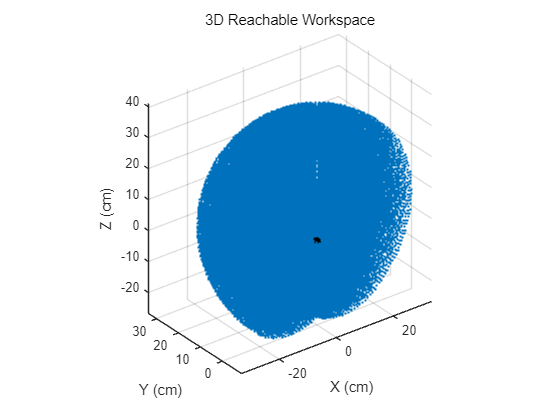


%% =========================================================
% Plot 1: 3D workspace
%% =========================================================
figure('Name','3D Workspace', 'NumberTitle','off');
scatter3(all_positions(:,1), all_positions(:,2), all_positions(:,3), 3, 'filled');
grid on; axis equal;
xlabel('X (cm)'); ylabel('Y (cm)'); zlabel('Z (cm)');
title('3D Reachable Workspace');
hold on;
plot3(0,0,0,'ko','MarkerFaceColor','k','MarkerSize',6);

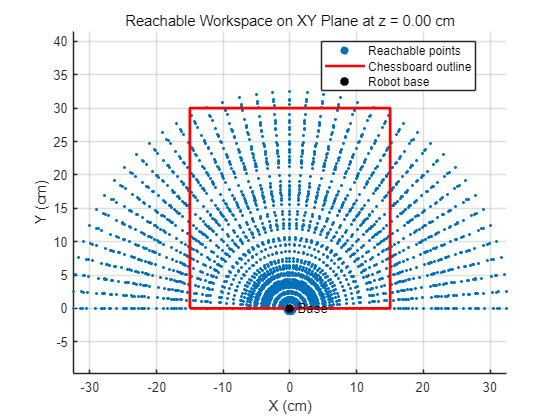


%% =========================================================
% Plot 2: XY workspace at chessboard height
%% =========================================================
figure('Name','XY Workspace', 'NumberTitle','off');
hold on; grid on; axis equal;

if ~isempty(xy_points)
    scatter(xy_points(:,1), xy_points(:,2), 5, 'filled');
end

board_x = [board_x_min, board_x_min + board_size, board_x_min + board_size, board_x_min, board_x_min];
board_y = [board_y_min, board_y_min, board_y_min + board_size, board_y_min + board_size, board_y_min];

plot(board_x, board_y, 'r-', 'LineWidth', 2);
plot(0,0,'ko','MarkerFaceColor','k','MarkerSize',6);
text(0,0,'  Base');

xlabel('X (cm)');
ylabel('Y (cm)');
title(sprintf('Reachable Workspace on XY Plane at z = %.2f cm', board_z));
legend('Reachable points', 'Chessboard outline', 'Robot base', 'Location', 'best');

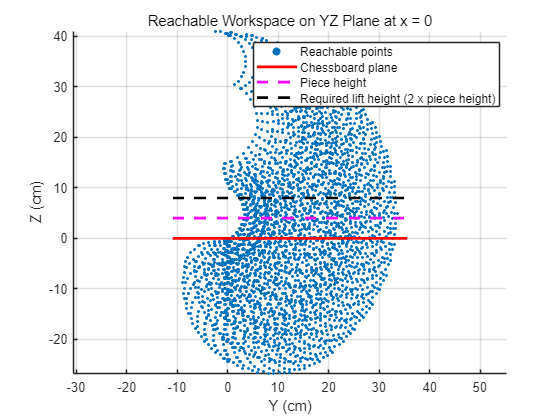


%% =========================================================
% Plot 3: YZ workspace at x = 0 (recommended centreline section)
%% =========================================================
figure('Name','YZ Workspace', 'NumberTitle','off');
hold on; grid on; axis equal;

if ~isempty(yz_points)
    scatter(yz_points(:,2), yz_points(:,3), 5, 'filled');
end

y_min_plot = min(all_positions(:,2)) - 2;
y_max_plot = max(all_positions(:,2)) + 2;

% Chessboard plane
plot([y_min_plot, y_max_plot], [board_z, board_z], 'r-', 'LineWidth', 2);

% Chess piece height
plot([y_min_plot, y_max_plot], [board_z + piece_height, board_z + piece_height], ...
    'm--', 'LineWidth', 2);

% Required lift height = 2 x piece height
plot([y_min_plot, y_max_plot], [board_z + lift_height, board_z + lift_height], ...
    'k--', 'LineWidth', 2);

xlabel('Y (cm)');
ylabel('Z (cm)');
title('Reachable Workspace on YZ Plane at x = 0');
legend('Reachable points', 'Chessboard plane', 'Piece height', ...
       'Required lift height (2 x piece height)', 'Location', 'best');


%% =========================================================
% Standard DH transform
%% =========================================================

function T = DH_std(a, alpha, d, theta)
ct = cos(theta);  st = sin(theta);
ca = cos(alpha);  sa = sin(alpha);

T = [ct, -st*ca,  st*sa, a*ct;
     st,  ct*ca, -ct*sa, a*st;
     0,      sa,     ca,    d;
     0,       0,      0,    1];
end